#### Задача 3.1.

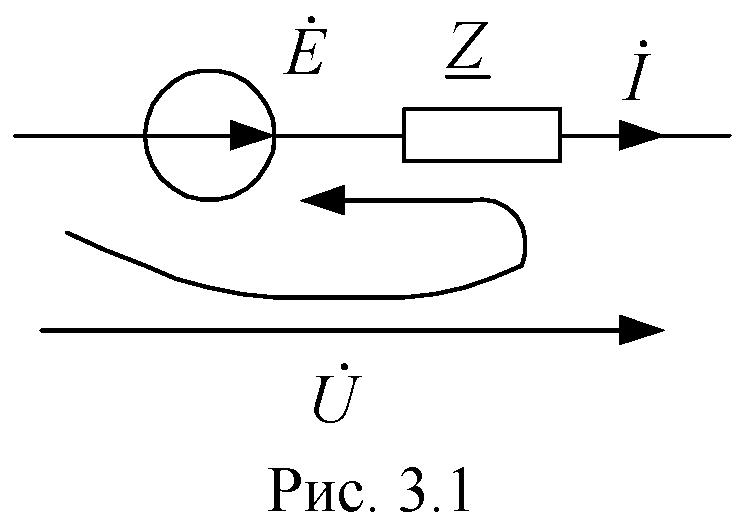

clear
format short
digits(3)
Ed_uz=220;
Id_uz=15*exp(-1j*pi/6);
Z_uz=4+2j;
% U-?


Уравнение 2-го закона Кирхгофа

syms Ud Id Z Ed
eq1=Ud-Id*Z==-Ed

$$eq1 = \mathrm{Ud}-\mathrm{Id}\,Z=-\mathrm{Ed}$$

Ud=solve(eq1,Ud)

$$Ud = \mathrm{Id}\,Z-\mathrm{Ed}$$

Ud=vpa(subs(Ud,[Id Z Ed],[Id_uz Z_uz Ed_uz]))

$$Ud = -153.0-4.02\,\mathrm{i}$$

U=abs(Ud)

$$U = 153.0$$

#### Задача 3.2.

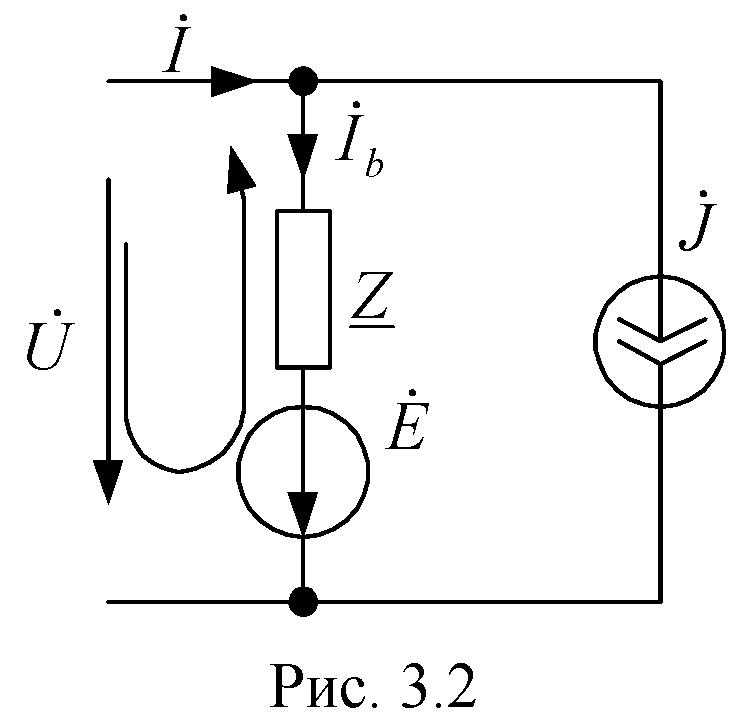

clear
digits(3)
U_uz=380;
E_uz=220*exp(1j*120*pi/180);
J_uz=-20j;
Z_uz=5-2j;


Уравнения Кирхгофа

syms I J I_b U Z E
eq1=-I+J+I_b==0,...
eq2=U-I_b*Z==-E

$$eq1 = I_{b}-\text{I}+J=0$$

$$eq2 = U-I_{b}\,Z=-\text{E}$$

U=380,E=220*exp(1j*120*pi/180),J=-20j,Z=5-2j

U = 380

E = -1.1000e+02 + 1.9053e+02i

J = -0.0000 - 20.0000i

Z = 5.0000 - 2.0000i


I_b=vpa((U+E)/Z), Ip_b=vpa([abs(I_b),angle(I_b)*180/pi])

$$I\_b = 33.4+51.5\,\mathrm{i}$$

$$Ip\_b = \left(\begin{array}{cc} 61.4 & 57.0 \end{array}\right)$$

I=vpa(I_b+J), Ip=vpa([abs(I),angle(I)*180/pi])

$$I = 33.4+31.5\,\mathrm{i}$$

$$Ip = \left(\begin{array}{cc} 45.9 & 43.3 \end{array}\right)$$

#### Задача 3.3.

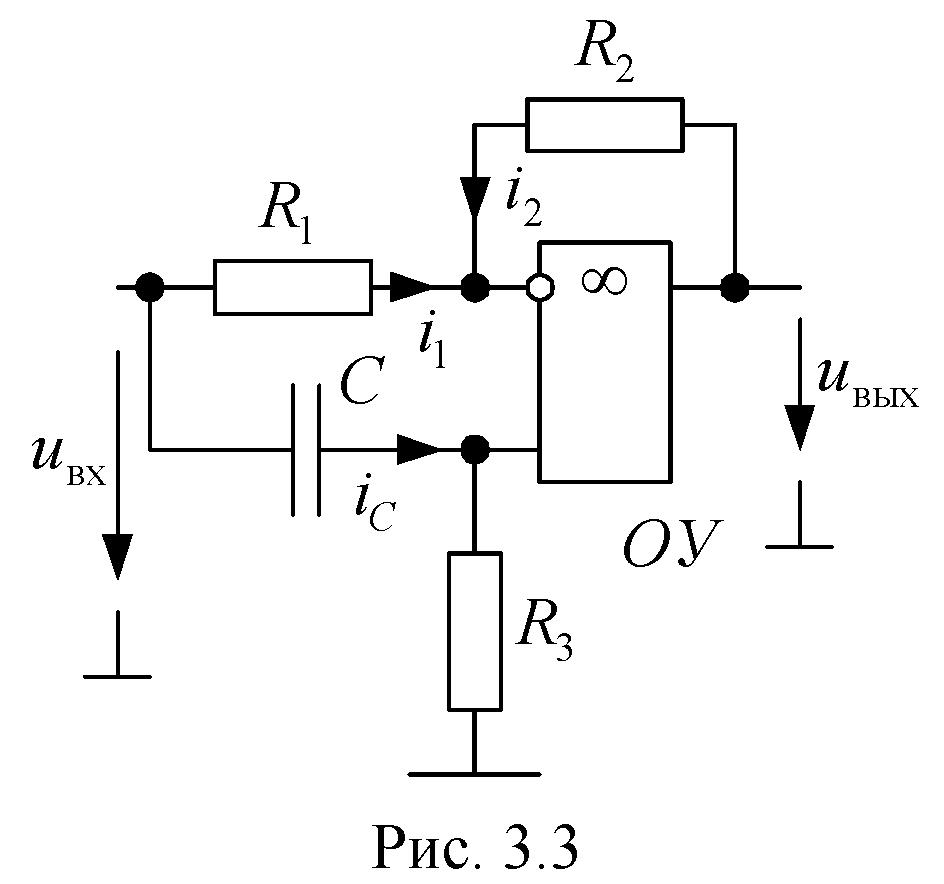

clear
R1=47e3;
R2=47e3;
R3=47e3;
R=47e3;
C=0.068e-6;
syms t
U_in=10*sin(314*t)

$$U\_in = 10\,\sin\left(314\,t\right)$$

omega=314

omega = 314

Um_in=10

Um_in = 10

U_in=vpa(Um_in/sqrt(2))

$$U\_in = 7.07$$

Уравнения Кирхгофа

syms I1 I2 U_in I_C Z R1 R2 U_out 
eq1=I1+I2==0,...
eq2=-U_in+I_C*Z,...
eq3=-U_in+I1*R1-I2*R2+U_out

$$eq1 = I_{1}+I_{2}=0$$

$$eq2 = I_{C}\,Z-U_{\mathrm{in}}$$

$$eq3 = U_{\mathrm{out}}-U_{\mathrm{in}}+I_{1}\,R_{1}-I_{2}\,R_{2}$$

Z=vpa(R-1j/(omega*C))

$$Z = 4.7e+4-4.68e+4\,\mathrm{i}$$

Um_R3=Um_in*R/Z

$$Um\_R3 = 5.02+5.0\,\mathrm{i}$$

Токи

im1=(Um_in-Um_R3)/R

$$im1 = 1.06e-4-1.06e-4\,\mathrm{i}$$

im2=-im1

$$im2 = -1.06e-4+1.06e-4\,\mathrm{i}$$

Выходное напряжение

Um_out=Um_in-im1*R+im2*R, Up_out=vpa([abs(Um_out),angle(Um_out)*180/pi])

$$Um\_out = 0.0354+10.0\,\mathrm{i}$$

$$Up\_out = \left(\begin{array}{cc} 10.0 & 89.8 \end{array}\right)$$